# Simulate AR(1) Autoregressive Processes 

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

## Mean and Standard Deviation for AR(1) Autoregressive Process 

A first-order autoregressive process can be written as:

- AR1: $X_t = \text{constant} + \text{persistence}\cdot x_{t-1} + \epsilon$

- AR1: $X_t = C + \rho\cdot x_{t-1} + \epsilon$

Assume that $\epsilon$ is mean zero

Note that, we know the mean of $X$:

- 
$$\mu_{X} = C + \rho\cdot\mu_{X} + 0$$


- 
$$\mu_x = \frac{C}{1-\rho}$$


Note that, we also know the standard deviation of $X$:

- 
$$\text{var}\left(X\right) = \rho^2 \cdot \text{var}\left(X\right) + \text{var}\left(\epsilon\right)$$


- 
$$\sigma_x = \sqrt{\frac{\sigma^2_{\epsilon}}{1-\rho^2}}$$


We will let the initial point of the time series follow the stationary distribution of the AR(1) process, then we simulate the time series over 100 periods, in the example below, we use a highly persistent shock process with $\rho=0.98$, $\sigma_{\epsilon} = 0.02$, $C=0.02$. Note that for this process:

- 
$$\mu_{x}^{\rho=0.98, \sigma_{\epsilon}=0.02, C=0.02} = \frac{0.02}{1-0.98}=1$$


- 
$$\sigma_{x}^{\rho=0.98, \sigma_{\epsilon}=0.02, C=0.02} = \sqrt{\frac{0.02^2}{1-0.98^2}}\approx0.10$$


## Simulated one First-Order Autoregressive Time-Series

In the Example below, we simulate an individual for 1000 periods, given $\rho=0.98$, $\sigma_{\epsilon} = 0.02$, $C=0.02$. Given that the process is highly persistent, the individual stays rich or poor for dozens of periods at a time. If each period is a year, look at the results below, and suppose the simulated time series is income, what is the process saying about this person's income rise and fall. Note that we have the same person through all 1000 periods, but if you only look at 50 periods (years), you might this this person during one span is really successful, anothe segment of 50 years, doing really bad, but actually there is nothing changing in the person's type, all that is changing is the person's luck.

First Set Parameters:

% Number of Time Periods
it_T = 1000;
% Mean and SD of the Shock Process
fl_constant = 0.02;
fl_normal_sd = 0.02;
% Persistence
fl_persistence = 0.98;
% Bounds on Shocks
fl_shk_bnds = 3;
% Initialize with exo fed point or not, if false initialize at Random Point
% from the stationary distribution
bl_init = true;
fl_init = fl_constant/(1 - fl_persistence);

Second, generate a vector of normal shocks:

% Generate a normal shock vector (the first draw will be ignored)
it_draws = it_T;
rng(789);
ar_fl_shocks = normrnd(0, fl_normal_sd, 1, it_draws);
disp(ar_fl_shocks(1:20));

   -0.0060   -0.0047    0.0168    0.0118    0.0380    0.0062   -0.0616   -0.0485   -0.0192    0.0023   -0.0197    0.0040    0.0156   -0.0089    0.0160    0.0099   -0.0200   -0.0206   -0.0090   -0.0069



Third, replace any values exceeding bounds:

% out of bounds indicators
fl_shk_bds_lower = 0 - fl_normal_sd*fl_shk_bnds;
fl_shk_bds_upper = 0 + fl_normal_sd*fl_shk_bnds;
ar_bl_outofbounds = (ar_fl_shocks <= fl_shk_bds_lower | ar_fl_shocks >= fl_shk_bds_upper);
% count out of bounds
disp(strcat('lower:', num2str(fl_shk_bds_lower), ', upper:', num2str(fl_shk_bds_upper)));

lower:-0.06, upper:0.06


disp(sum(ar_bl_outofbounds));

     4



ar_fl_shocks(ar_fl_shocks <= fl_shk_bds_lower) = fl_shk_bds_lower;
ar_fl_shocks(ar_fl_shocks >= fl_shk_bds_upper) = fl_shk_bds_upper;

Fourth, generate the AR(1) time series:

% Initialize Output Array
ar_fl_time_series = zeros(size(ar_fl_shocks));
% Loop over time
for it_t=1:1:length(ar_fl_shocks)
    if (it_t == 1)
        % initialize using the ean of the process
        ar_fl_time_series(1) = fl_constant/(1 - fl_persistence);
        if (bl_init)
            ar_fl_time_series(1) = fl_init;            
        end
    else
        fl_ts_t = fl_constant + ar_fl_time_series(it_t-1)*fl_persistence + ar_fl_shocks(it_t);
        ar_fl_time_series(it_t) = fl_ts_t;
    end
end

Fifth, show the mean and sd of the process (these are very close to the analytical results):

disp(mean(ar_fl_time_series));

    1.0104



disp(std(ar_fl_time_series));

    0.1000



Sixth, plot the results:

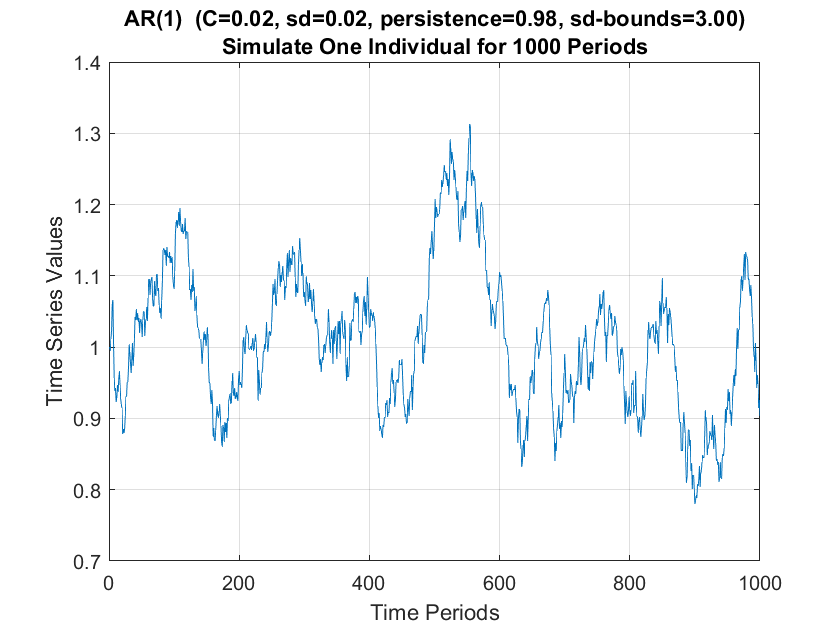

figure();
% x-axis
ar_it_time = 1:1:length(ar_fl_shocks);
% plot
plot(ar_it_time, ar_fl_time_series);
% Generate Title
ar_fl_params_values = [fl_constant, fl_normal_sd, fl_persistence, fl_shk_bnds];
ar_st_parms_names = ["C", "sd", "persistence", "sd-bounds"];
st_rounding = '.2f';
st_title_main = "AR(1) ";
ar_st_params = strcat(ar_st_parms_names, compose(strcat("=%", st_rounding), ar_fl_params_values));
st_param_pasted = strjoin(ar_st_params, ', ');
st_title_wth_params = strcat(st_title_main, ' (', st_param_pasted, ')');
title({st_title_wth_params, 'Simulate One Individual for 1000 Periods'});
% X and Y labels
ylabel({'Time Series Values'});
xlabel('Time Periods');
grid on;

## Income Process for India (Monthly)

In the Example below, we simulate an individual for 1000 periods. In the example below, the parameters are from estiamting an AR(1) process for log of income in India, see Udupa and Wang (2020). We can use the [ff_simu_stats](https://fanwangecon.github.io/MEconTools/MEconTools/doc/stats/htmlpdfm/fx_simu_stats.html) function from [MEconTools](https://fanwangecon.github.io/MEconTools/) to look at the distributional information from this time series, we care about income, so we will exponentiate the log of income we obtained. 

Note that for the distributional results, GINI, share of income held by different percentiles of households, is invariant to the choice of the $C$ constant term earlier. Try changing that number, the distributional statistics that we obtain below will be the same. Also note that the exponential of the mean of the log of income is not equal to the mean of income. 

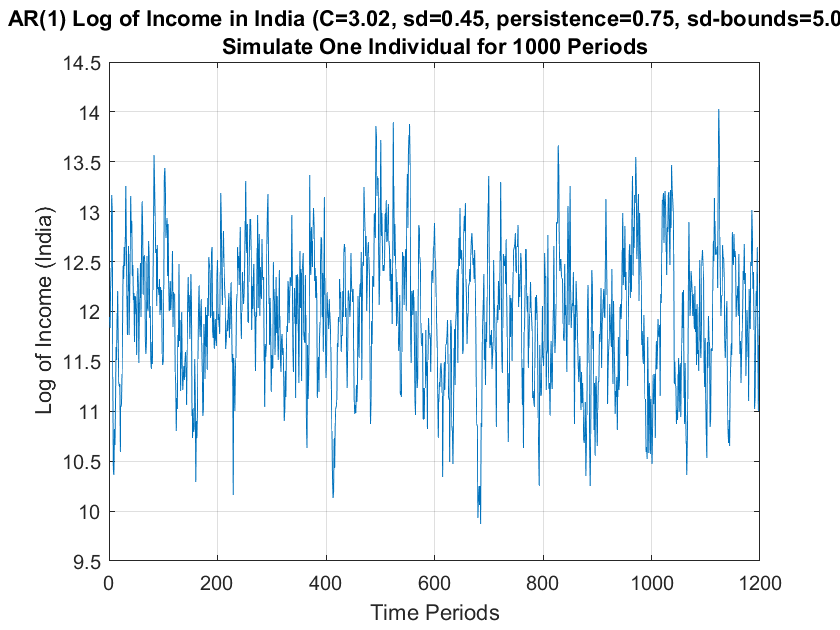

% Number of Time Periods (Months) 100 years time series.
% Note that if multiple individuals share the same process, the lack of
% time spans can be compensated by higher numbers of observations
it_T = 12*100;
% Mean and SD of the Shock Process
fl_constant = 3.024467;
fl_normal_sd = 0.45;
% Persistence
fl_persistence = 0.7468;
% Bounds on Shocks
fl_shk_bnds = 5;
% Initialize with exo fed point or not, if false initialize at Random Point
% from the stationary distribution
bl_init = true;
fl_init = fl_constant/(1 - fl_persistence);
% Generate a normal shock vector (the first draw will be ignored)
it_draws = it_T;
rng(789);
ar_fl_shocks = normrnd(0, fl_normal_sd, 1, it_draws);
% out of bounds indicators
fl_shk_bds_lower = 0 - fl_normal_sd*fl_shk_bnds;
fl_shk_bds_upper = 0 + fl_normal_sd*fl_shk_bnds;
ar_bl_outofbounds = (ar_fl_shocks <= fl_shk_bds_lower | ar_fl_shocks >= fl_shk_bds_upper);
ar_fl_shocks(ar_fl_shocks <= fl_shk_bds_lower) = fl_shk_bds_lower;
ar_fl_shocks(ar_fl_shocks >= fl_shk_bds_upper) = fl_shk_bds_upper;
% Initialize Output Array
ar_fl_time_series = zeros(size(ar_fl_shocks));
% Loop over time
for it_t=1:1:length(ar_fl_shocks)
    if (it_t == 1)
        % initialize using the ean of the process
        ar_fl_time_series(1) = fl_constant/(1 - fl_persistence);
        if (bl_init)
            ar_fl_time_series(1) = fl_init;            
        end
    else
        fl_ts_t = fl_constant + ar_fl_time_series(it_t-1)*fl_persistence + ar_fl_shocks(it_t);
        ar_fl_time_series(it_t) = fl_ts_t;
    end
end
ar_series = (ar_fl_time_series);
fl_mean = mean(ar_series);
fl_std = std(ar_series);
% Visualize
figure();
% x-axis
ar_it_time = 1:1:length(ar_fl_shocks);
% plot
plot(ar_it_time, (ar_fl_time_series));
% Generate Title
ar_fl_params_values = [fl_constant, fl_normal_sd, fl_persistence, fl_shk_bnds];
ar_st_parms_names = ["C", "sd", "persistence", "sd-bounds"];
st_rounding = '.2f';
st_title_main = "AR(1) Log of Income in India";
ar_st_params = strcat(ar_st_parms_names, compose(strcat("=%", st_rounding), ar_fl_params_values));
st_param_pasted = strjoin(ar_st_params, ', ');
st_title_wth_params = strcat(st_title_main, ' (', st_param_pasted, ')');
title({st_title_wth_params, 'Simulate One Individual for 1000 Periods'});
% X and Y labels
ylabel({'Log of Income (India)'});
xlabel('Time Periods');
grid on;

% Set Parameters
mp_cl_mt_xyz_of_s = containers.Map('KeyType','char', 'ValueType','any');
mp_cl_mt_xyz_of_s('log_income') = {(ar_series), zeros(1)};
mp_cl_mt_xyz_of_s('income') = {exp(ar_series), zeros(1)};
mp_cl_mt_xyz_of_s('ar_st_y_name') = ["log_income", "income"];
% Mass
rng(123);
mt_f_of_s = zeros(size(ar_series)) + 1/numel(ar_series);
mt_f_of_s = mt_f_of_s/sum(mt_f_of_s, 'all');
mp_cl_mt_xyz_of_s_out = ff_simu_stats(mt_f_of_s, mp_cl_mt_xyz_of_s);

xxx tb_outcomes: all stats xxx
    OriginalVariableNames    log_income      income  
    _____________________    __________    __________

    {'mean'             }        11.961    1.9596e+05
    {'unweighted_sum'   }         14353    2.3515e+08
    {'sd'               }       0.67819    1.4374e+05
    {'coefofvar'        }      0.056701       0.73353
    {'gini'             }      0.031982       0.36159
    {'min'              }        9.8742         19423
    {'max'              }        14.031    1.2403e+06
    {'pYis0'            }             0             0
    {'pYls0'            }             0             0
    {'pYgr0'            }             1             1
    {'pYisMINY'         }    0.00083333    0.00083333
    {'pYisMAXY'         }    0.00083333    0.00083333
    {'p1'               }        10.295         29579
    {'p10'              }        11.075         64566
  

## Aggregate Income Process for India: Monthly, Annual, and Quadrennial 

There is a discrete AR(1) income process happening at the monthly level. However, we only observe aggregate information from the course of an entire year; no monthly data is available, but we know the total income from the year. What is the persistence in annual income from year to year? What if we only observe data every four years? What happens to monthly persistence at the annualized and quadrennial level?

When the underlying process is AR(1), it is important to remember that this process does not shift up or down over the long run, when we aggregate over sufficient time-horizon, there will be no persistence in the process left. When the underlying process is more persistence, persistence is preserved at greater spans of aggregation. 

Here, suppose that there are 12 months in a year. We interpret the time-series just generated as the monthly time-series. We keep only all full 12 months data segments, dropping data from the last incomplete year. We reshape the vector of data to a matrix with 12 rows and some $M$ columns, and we compute the column sum in income. We proceed similarly to by aggregating over 48 months of data for the quadrennial analysis. We will regress monthly value on lagged monthly value, and also regress annual aggregate on lagged annual aggregate. What are the coefficients that we get? We will use matlab's [fitlm](https://www.mathworks.com/help/stats/fitlm.html) package. Synatx is similar to lm regression in R.

First, we generate the data structures.

% A1. Cut from monthly series last incomplete year
it_month_per_year = 12;
ar_fl_monthly_series = ar_fl_time_series;
it_months = length(ar_fl_monthly_series);
it_years = floor(it_months/it_month_per_year);
it_mth_fullyr = it_month_per_year*it_years;
ar_fl_monthly_series_full_year = ar_fl_monthly_series(1:(it_mth_fullyr));
% A2. For testing purposes, suppose only observe average data every four years.
it_m48_per_year = 48;
ar_fl_m48ly_series = ar_fl_time_series;
it_m48s = length(ar_fl_m48ly_series);
it_4years = floor(it_m48s/it_m48_per_year);
it_mth_4yr = it_m48_per_year*it_4years;
ar_fl_m48ly_series_48m_year = ar_fl_m48ly_series(1:(it_mth_4yr));

% B1. Generate annualized (sum or average the same) statistics
mt_fl_monthly_series = reshape(ar_fl_monthly_series_full_year, [it_month_per_year, it_years]);
ar_fl_annual_mean_series = mean(mt_fl_monthly_series, 1);
% B2. Generate 48 month aggregate results
mt_fl_m48ly_series = reshape(ar_fl_m48ly_series_48m_year, [it_m48_per_year, it_4years]);
ar_fl_quadrennial_mean_series = mean(mt_fl_m48ly_series, 1);

Second, we create tables with current and lagged data.

% C. Generate the regression inputs for monthly and annualized data
% C1. monthly lagged and current
ar_fl_monthly_tcur = [ar_fl_monthly_series_full_year(2:it_mth_fullyr)];
ar_fl_monthly_tlag = [ar_fl_monthly_series_full_year(1:(it_mth_fullyr-1))];
tb_monthly_ar1 = table(ar_fl_monthly_tcur', ar_fl_monthly_tlag');
cl_col_names = {'y_mth_t', 'y_mth_t_lag'};
cl_row_names = strcat('mth_', string((2:(it_mth_fullyr))));
tb_monthly_ar1.Properties.VariableNames = matlab.lang.makeValidName(cl_col_names);
tb_monthly_ar1.Properties.RowNames = matlab.lang.makeValidName(cl_row_names);

% C2. annual lagged and current
ar_fl_annual_tcur = [ar_fl_annual_mean_series(2:it_years)];
ar_fl_annual_tlag = [ar_fl_annual_mean_series(1:(it_years-1))];
tb_annual_ar1 = table(ar_fl_annual_tcur', ar_fl_annual_tlag');
cl_col_names = {'y_annual_t', 'y_annual_t_lag'};
cl_row_names = strcat('year_', string((2:(it_years))));
tb_annual_ar1.Properties.VariableNames = matlab.lang.makeValidName(cl_col_names);
tb_annual_ar1.Properties.RowNames = matlab.lang.makeValidName(cl_row_names);

% C3. every 4 year info
ar_fl_quadrennial_tcur = [ar_fl_quadrennial_mean_series(2:it_4years)];
ar_fl_quadrennial_tlag = [ar_fl_quadrennial_mean_series(1:(it_4years-1))];
tb_quadrennial_ar1 = table(ar_fl_quadrennial_tcur', ar_fl_quadrennial_tlag');
cl_col_names = {'y_quadrennial_t', 'y_quadrennial_t_lag'};
cl_row_names = strcat('4year_', string((2:(it_4years))));
tb_quadrennial_ar1.Properties.VariableNames = matlab.lang.makeValidName(cl_col_names);
tb_quadrennial_ar1.Properties.RowNames = matlab.lang.makeValidName(cl_row_names);

## Visaulize Indian Monthly Income Regression

We regress current on lagged values for monthly data. We recoever exactly the AR(1) persistence parameter we used for the Indian simulation.

We have already visualized the time-series earlier. So first here, we visualize the correlation over time using a scatterplot

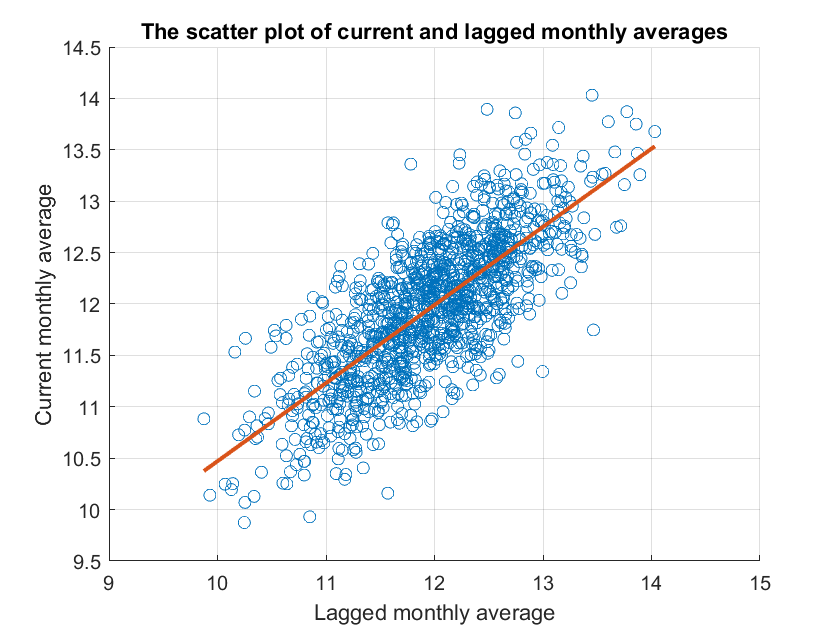

figure();
hold on;
% scatter
scatter(ar_fl_monthly_tlag, ar_fl_monthly_tcur);
% trend line
p = polyfit(ar_fl_monthly_tlag, ar_fl_monthly_tcur, 1);
px = [min(ar_fl_monthly_tlag) max(ar_fl_monthly_tlag)];
py = polyval(p, px);
plot(px, py, 'LineWidth', 2);
% labels
xlabel('Lagged monthly average');
ylabel('Current monthly average');
title('The scatter plot of current and lagged monthly averages')
grid on

Second, we regress.

% Regression
res_lm_monthly = fitlm(tb_monthly_ar1, 'y_mth_t~y_mth_t_lag');
disp(res_lm_monthly);

Linear regression model:
    y_mth_t ~ 1 + y_mth_t_lag

Estimated Coefficients:
                   Estimate      SE       tStat       pValue   
                   ________    _______    ______    ___________

    (Intercept)     2.8711      0.2251    12.755     4.9951e-35
    y_mth_t_lag    0.75997     0.01879    40.445    3.7303e-226


Number of observations: 1199, Error degrees of freedom: 1197
Root Mean Squared Error: 0.441
R-squared: 0.577,  Adjusted R-Squared: 0.577
F-statistic vs. constant model: 1.64e+03, p-value = 3.73e-226


## Indian Aggregate Annual Income Persistence

We regress current on lagged values for annual average data. Note that the correlation weakens.

First, visualize the time series.

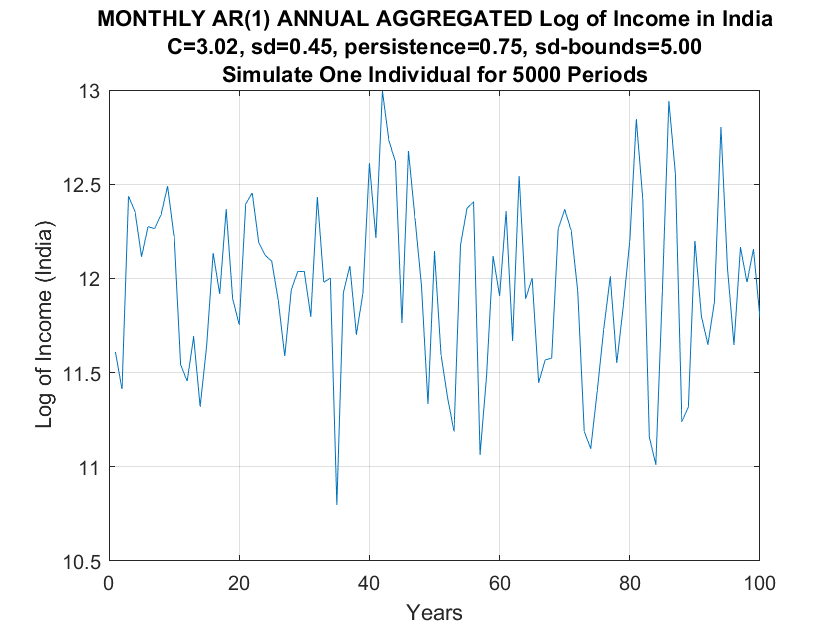

% Visualize 
figure();
% x-axis
ar_it_time = 1:1:length(ar_fl_annual_mean_series);
% plot
plot(ar_it_time, (ar_fl_annual_mean_series));
% Generate Title
ar_fl_params_values = [fl_constant, fl_normal_sd, fl_persistence, fl_shk_bnds];
ar_st_parms_names = ["C", "sd", "persistence", "sd-bounds"];
st_rounding = '.2f';
st_title_main = "MONTHLY AR(1) ANNUAL AGGREGATED Log of Income in India";
ar_st_params = strcat(ar_st_parms_names, compose(strcat("=%", st_rounding), ar_fl_params_values));
st_param_pasted = strjoin(ar_st_params, ', ');
title({st_title_main, st_param_pasted, ...
    'Simulate One Individual for 5000 Periods'});
% X and Y labels
ylabel({'Log of Income (India)'});
xlabel('Years');
grid on;

Second, visualize via scatter plot.

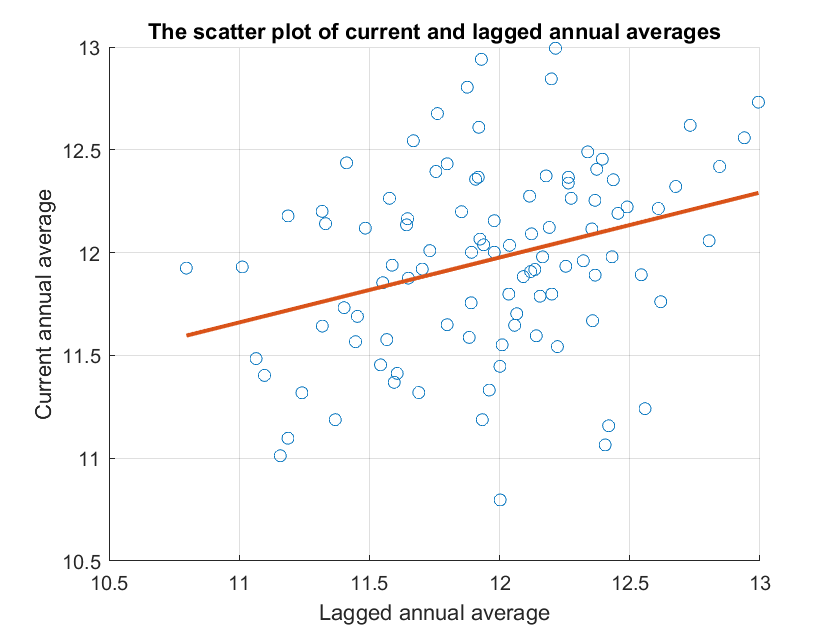

figure();
hold on;
% scatter
scatter(ar_fl_annual_tlag, ar_fl_annual_tcur);
% trend line
p = polyfit(ar_fl_annual_tlag, ar_fl_annual_tcur, 1);
px = [min(ar_fl_annual_tlag) max(ar_fl_annual_tlag)];
py = polyval(p, px);
plot(px, py, 'LineWidth', 2);
% labels
xlabel('Lagged annual average');
ylabel('Current annual average');
title('The scatter plot of current and lagged annual averages')
grid on

Third, regression.

% Regression
res_lm_annual = fitlm(tb_annual_ar1, 'y_annual_t~y_annual_t_lag');
disp(res_lm_annual);

Linear regression model:
    y_annual_t ~ 1 + y_annual_t_lag

Estimated Coefficients:
                      Estimate       SE       tStat       pValue  
                      ________    ________    ______    __________

    (Intercept)         8.185       1.1503    7.1158    1.9255e-10
    y_annual_t_lag    0.31594     0.096084    3.2881     0.0014058


Number of observations: 99, Error degrees of freedom: 97
Root Mean Squared Error: 0.437
R-squared: 0.1,  Adjusted R-Squared: 0.091
F-statistic vs. constant model: 10.8, p-value = 0.00141


## Indian Aggregate Quadrennial Income Persistence

Fifth, we regress current on lagged values for quadrennial average data. Note that we now have an insignificant negative correlation. An important concept for AR(1) processes is that over long-horizon, we are just fluctuating, and moving up or down. The long term aggregate pattern is flat. Persistence weakens until it is lost when data is aggregated. AR(1) becomes by construction noise. 

First, visualize the time series.

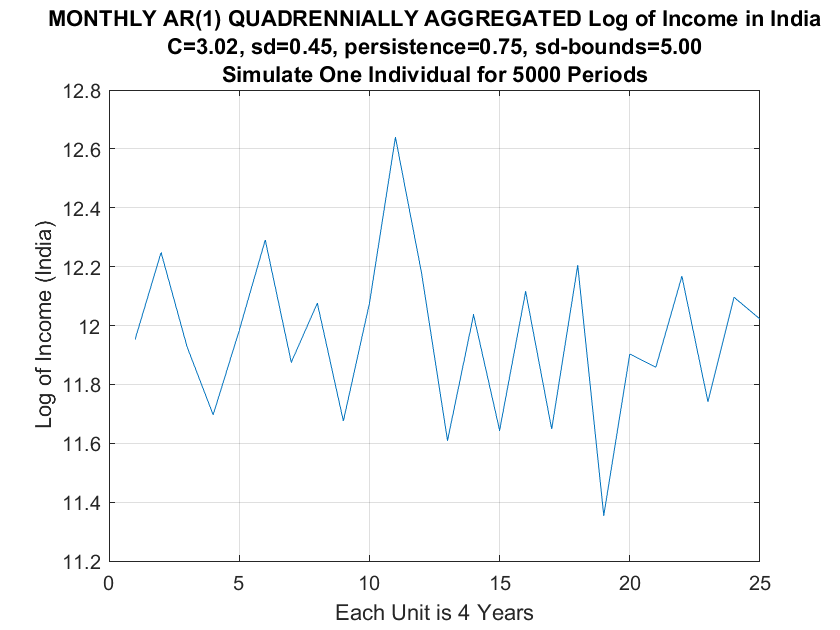

% Visualize 
figure();
% x-axis
ar_it_time = 1:1:length(ar_fl_quadrennial_mean_series);
% plot
plot(ar_it_time, (ar_fl_quadrennial_mean_series));
% Generate Title
ar_fl_params_values = [fl_constant, fl_normal_sd, fl_persistence, fl_shk_bnds];
ar_st_parms_names = ["C", "sd", "persistence", "sd-bounds"];
st_rounding = '.2f';
st_title_main = "MONTHLY AR(1) QUADRENNIALLY AGGREGATED Log of Income in India";
ar_st_params = strcat(ar_st_parms_names, compose(strcat("=%", st_rounding), ar_fl_params_values));
st_param_pasted = strjoin(ar_st_params, ', ');
title({st_title_main, st_param_pasted, ...
    'Simulate One Individual for 5000 Periods'});
% X and Y labels
ylabel({'Log of Income (India)'});
xlabel('Each Unit is 4 Years');
grid on;

Second, visualize via scatter plot.

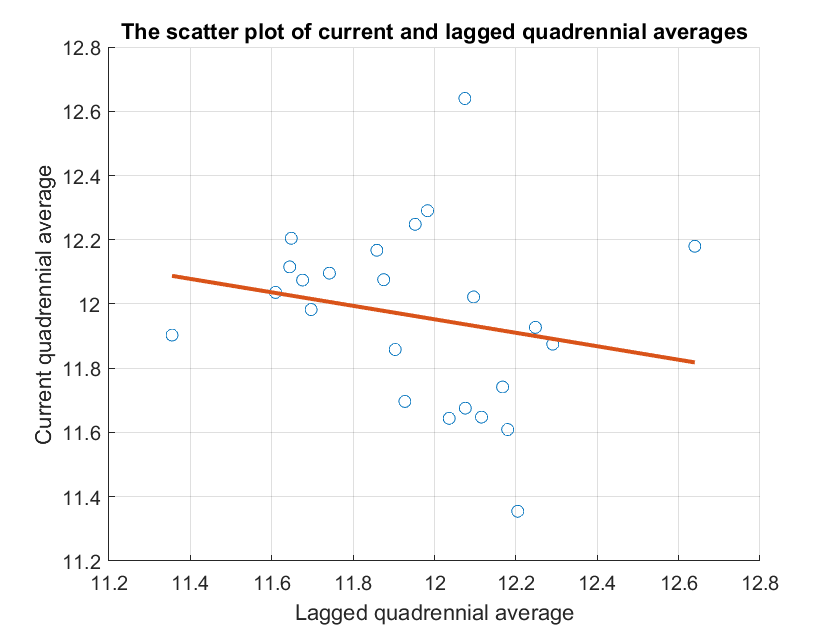

figure();
hold on;
% scatter
scatter(ar_fl_quadrennial_tlag, ar_fl_quadrennial_tcur);
% trend line
p = polyfit(ar_fl_quadrennial_tlag, ar_fl_quadrennial_tcur, 1);
px = [min(ar_fl_quadrennial_tlag) max(ar_fl_quadrennial_tlag)];
py = polyval(p, px);
plot(px, py, 'LineWidth', 2);
% labels
xlabel('Lagged quadrennial average');
ylabel('Current quadrennial average');
title('The scatter plot of current and lagged quadrennial averages')
grid on

Third, regression.

% Regression
res_lm_quadrennial = fitlm(tb_quadrennial_ar1, 'y_quadrennial_t~y_quadrennial_t_lag');
disp(res_lm_quadrennial);

Linear regression model:
    y_quadrennial_t ~ 1 + y_quadrennial_t_lag

Estimated Coefficients:
                           Estimate      SE       tStat       pValue  
                           ________    _______    ______    __________

    (Intercept)              14.469     2.4962    5.7964    7.8514e-06
    y_quadrennial_t_lag    -0.20974    0.20869    -1.005       0.32582


Number of observations: 24, Error degrees of freedom: 22
Root Mean Squared Error: 0.279
R-squared: 0.0439,  Adjusted R-Squared: 0.000436
F-statistic vs. constant model: 1.01, p-value = 0.326
